clc
clear

Load data

files = dir('Data\Km2\scope_*.csv');
measurement = zeros(length(files),1);
i = 1;
for file = files'
    data = readmatrix(strcat("Data\Km2\",file.name),Range=[4,2]);
    measurement(i) = mean(data);
    i= i+1;
end

Convert to $\omega$ and $\tau$

voltage_To_Toqrue = 2/10;
torque = -measurement * voltage_To_Toqrue;
omega = (linspace(0,1,21)) * 1059;

Plot the measurements

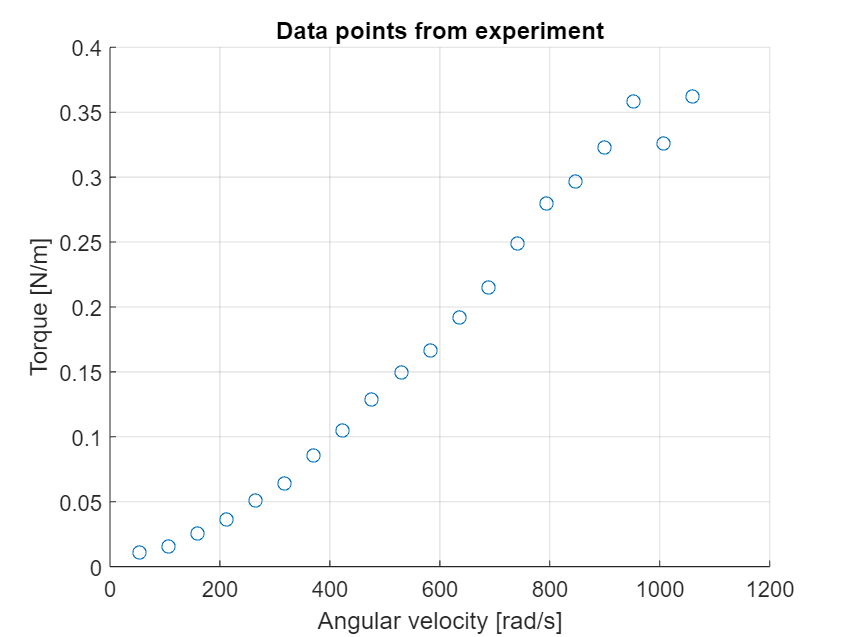

scatter(omega(2:end),torque)
grid on
title('Data points from experiment')
xlabel('Angular velocity [rad/s]');
ylabel('Torque [N/m]')
saveas(gcf,'Images/Omega_To_Torque_Data','epsc')

Performe and plot regression

xreg = omega(2:end);
yreg = torque.';
[fitresult, gof] = createFit(xreg,yreg)

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    0.000327  (0.0003072, 0.0003468)
       p2 =           0  (fixed at bound)

gof = struct with fields:
           sse: 0.0137
       rsquare: 0.9517
           dfe: 19
    adjrsquare: 0.9517
          rmse: 0.0268


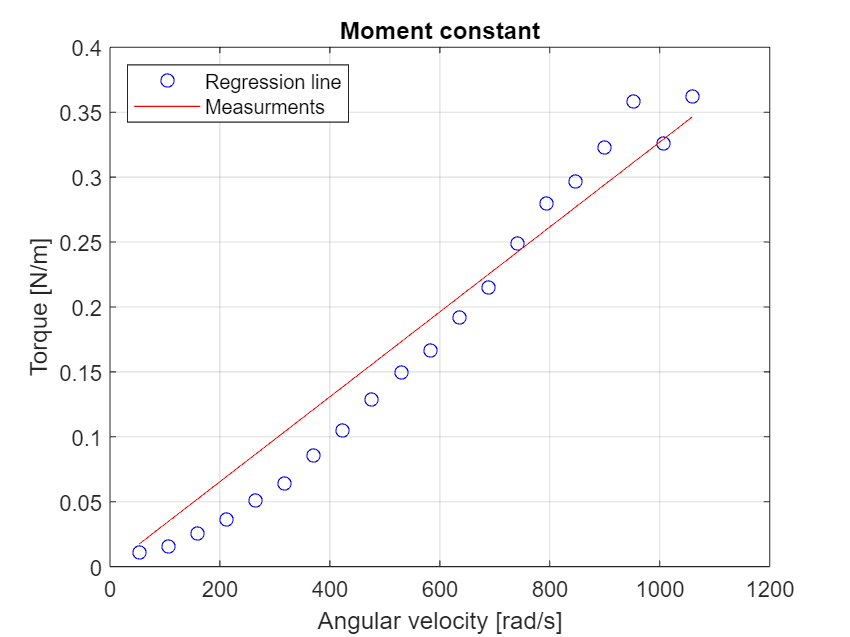

plot( fitresult,'r-', xreg, yreg,'bo' );
grid on
title('Moment constant')
xlabel('Angular velocity [rad/s]');
ylabel('Torque [N/m]')
legend('Regression line','Measurments','location','northwest')
saveas(gcf,'Images/Omega_To_Torque_Reg','epsc')